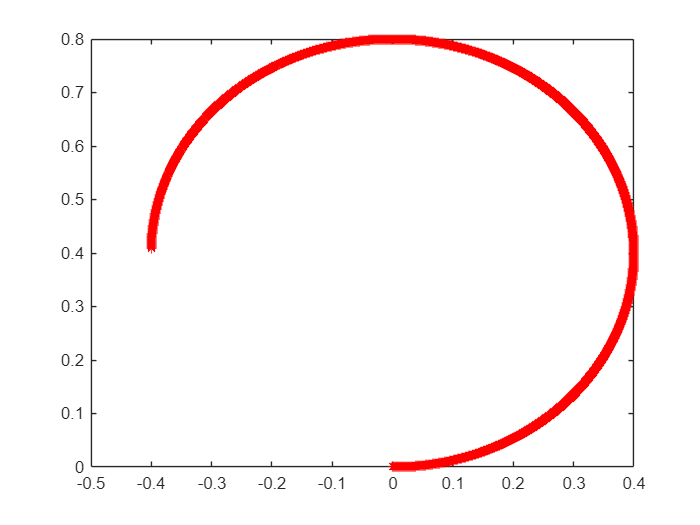

x = 0;
y = 0;
o=0;
K = 0.8; % m
r = 0.1; % m
tau = 0.12; % s
dt = 0.025; % s


wid = 0;
wdd = 1;

G = tf(1/tau,[1 1/tau]);
Gz = c2d(G,dt);
wi = wid*step(Gz,2);
wd = wdd*step(Gz,2);

%wi = wid*(0.12*exp(-deltat/0.12));
%wd = wdd*(0.12*exp(-deltat/0.12));

if (wi>15)
    wi = 15;
end
if (wi<-15)
    wi = -15;
end
if (wd>15)
    wd = 15;
end
if (wd<-15)
    wd = -15;
end

v = (wi+wd)*r/2;
w = (wd-wi)*r/K;

deltas = v*dt;
deltao = w*dt;

figure
plot(0,0,"*b")
hold on
for i=1:1500
    o = o + deltao;
    deltax = cos(o).*deltas;
    deltay = sin(o).*deltas;
    x = x + deltax;
    y = y + deltay;
    plot(x,y,"*r")
end